# RVC toolbox: ikcon

Este método trabaja de manera similar al método ikunc, sólo que los límites conjuntos se consideran en esta solución.

q = R.ikunc (T) son las coordenadas de la articulación (1xN) correspondientes a la pose del efector final del robot T (4x4) que es una transformada homogénea, y N es el número de articulaciones del robot.

[q, err] = robot.ikunc (T) como arriba pero también devuelve err, que es el valor escalar final de la función objetivo.

[q, err, exitflag] = robot.ikunc (T) como arriba pero también devuelve el estado exitflag de fminunc.

[q, err, exitflag] = robot.ikunc (T, q0) como se indicó anteriormente, pero especifique las coordenadas de unión iniciales q0 utilizadas para la minimización.

[q, err, exitflag] = robot.ikunc (T, q0, options) como arriba, pero especifique las opciones para que fminunc las utilice.

**Operación de trayectoria**

En todos los casos, si T es 4x4xM, se toma como una secuencia de transformada homogénea y R.ikunc () devuelve las coordenadas conjuntas correspondientes a cada una de las transformadas en la secuencia. q es MxN donde N es el número de articulaciones del robot. La estimación inicial de q para cada paso de tiempo se toma como la solución del paso de tiempo anterior.

err y exitflag también son Mx1 e indican los resultados de la optimización para el paso de trayectoria correspondiente.

**Notas**

- Requiere fminunc de Optimization Toolbox.

- Los límites conjuntos sí se consideran en esta solución.

- Puede utilizarse para robots con grados de libertad arbitrarios.

- En el caso de múltiples soluciones factibles, la solución devuelta depende de la elección inicial de Q0

- Funciona minimizando el error entre la cinemática de avance de la solución del ángulo de articulación y el marco del efector final como optimización. La función objetivo (error) se describe como:


$$\textrm{sumsqr}\left(\left(\textrm{inv}\left(T\right)*\textrm{robot}\ldotp \textrm{fkine}\left(q\right)-\textrm{eye}\left(4\right)\right)*\textrm{omega}\right)$$


Donde omega es una matriz de ganancia, actualmente no modificable.

A continuación se presenta un ejemplo

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

%Se crean links, el primer parametro de la funcioón correspode al tipo de articulación. 
% En este caso todas son de tipo rotacional. Después se ingresan los
% parámetros alpha, a, d y offset. Luego se indica que los parametros
% corresponden a MDH. Finalmente se indican los rangos de operación.

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 

qSolve = Robot_ABB.ikcon(Target); 	%inverse kinematics usando optimización con límites de articulación

q1 = qSolve(1)%*(180/pi)

q1 = 0.8315

q2 = qSolve(2)%*(180/pi)

q2 = 0.5475

q3 = qSolve(3)%*(180/pi)

q3 = -0.2733

q4 = qSolve(4)%*(180/pi)

q4 = -2.3646

q5 = qSolve(5)%*(180/pi)

q5 = -1.2714

q6 = qSolve(6)%*(180/pi)

q6 = 0.0592

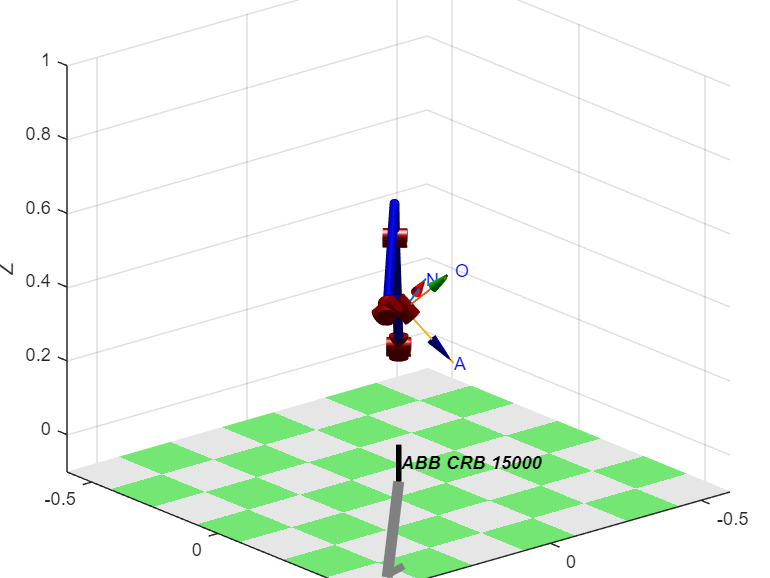

Robot_ABB.plot([q1 q2 q3 q4 q5 q6],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

Target

Target =    -0.8330   -0.3504   -0.4282    0.4000
   -0.5449    0.6541    0.5247    0.5000
    0.0962    0.6704   -0.7358    0.6000
         0         0         0    1.0000


Robot_ABB.fkine([q1 q2 q3 q4 q5 q6])

ans =    -0.8331   -0.3502   -0.4281    0.3999
   -0.5447    0.6541    0.5248    0.5000
    0.0963    0.6704   -0.7357    0.6000
         0         0         0    1.0000


### Conclusión

Se aprecia que el resultado no es exacto. Sin embargo se acerca mucho, el error es de decimales, casi insignificante. Por otro lado, todas las soluciones que se generen son totalmente válidas. Esto se da puesto que sí se tienen en cuenta los límites de las articulaciones en la solución.